## $R_T$ y $R_0$ para el modelo de 5 ecuaciones

addpath('/home/curie/MATLAB-Drive/ChimeraAedes/Chimera SEIR Vectorial/5 eqs')

T.Properties.CustomProperties.output = 1:8;
T.Properties.CustomProperties.Domain = [0 100];
ysim = gsua_deval(EstimatedParams(1,:), T, 0:100);

help R_t

 R_t
     R_t = R_t(H_I,H_S,M_I,M_S,N_H,GAMMA,MU_H,MU_M,Z_H,Z_M)



LengthY = length(ysim);
Result=zeros(1,LengthY);

gamma = exp(-EstimatedParams(1,5));
mu_h = EstimatedParams(1, 7);
mu_m = exp(-EstimatedParams(1, 6));
z_h = EstimatedParams(1, 9);
z_m =  EstimatedParams(1, 8);

for i = 1 : LengthY
    N_H = sum(ysim(1:3, i));
    Result(i) = vpa(R_t(ysim(2, i), ysim(1, i), ysim(5, i), ysim(4, i),N_H,...
                gamma, mu_h, mu_m, z_h, z_m));
end

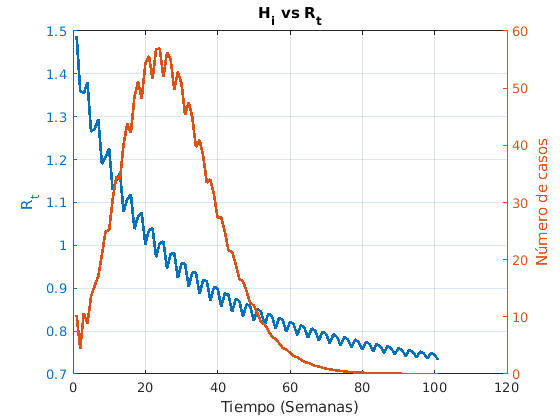

close all

title('H_i vs R_t')

yyaxis right
plot(ysim(7,:),'LineWidth',2)
ylabel('Número de casos')

yyaxis left
plot(abs(Result),'LineWidth',2)
ylabel('R_t')
xlabel("Tiempo (Semanas)")
grid on

help R_0

 R_0
     R_0 = R_0(M_I,M_S,N_H,GAMMA,MU_H,MU_M,Z_H,Z_M)



N_H = sum(ysim(1:3, 1));
C = EstimatedParams(1, 11);
r = EstimatedParams(1, 10);

abs(R_0(0,sum(ysim(4:5, end)), N_H, gamma, mu_h, mu_m, z_h,z_m))

ans = 0.7366